# Signal Processing Framework

## Fetal Heartbeat Signal Selection 

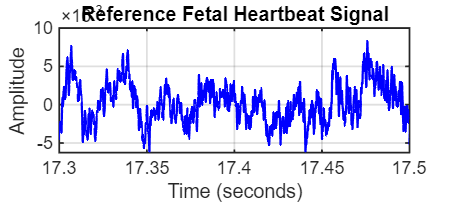

[filename, pathname] = uigetfile({'*.wav', 'WAV Files (*.wav)'}, 'Select a WAV file');
if isequal(filename, 0)
    disp('User canceled file selection.');
    return;
end

filePath = fullfile(pathname, filename);
[Fetalsignal, fsFetal] = audioread(filePath);

if size(Fetalsignal, 2) == 2
    Fetalsignal = mean(Fetalsignal, 2);
end

% Time vector for fetal signal
tFetal = (0:length(Fetalsignal)-1) / fsFetal;
% Create fetal signal plot
figure('Units','centimeters','Position',[5 5 18 8]);

plot(tFetal, Fetalsignal, 'b', 'LineWidth', 1.5);
xlabel('Time (seconds)', 'FontSize', 14);
ylabel('Amplitude', 'FontSize', 14);
title('Reference Fetal Heartbeat Signal', 'FontSize', 16);
xlim([17.3, 17.5]);

grid on;
set(gca, 'FontSize', 12, 'LineWidth', 1.2);
exportgraphics(gcf, 'FetalSignal_Raw.pdf', 'ContentType', 'vector');

## Maternal Heartbeat Signal Selection

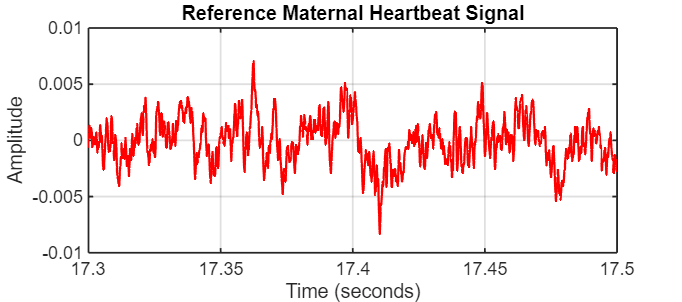

[filenameMaternal, pathnameMaternal] = uigetfile({'*.wav', 'WAV Files (*.wav)'}, 'Select the Maternal Heartbeat WAV File');
if isequal(filenameMaternal, 0)
    disp('User canceled maternal heartbeat file selection.');
    return;
end

filePathMaternal = fullfile(pathnameMaternal, filenameMaternal);
[maternalSignal, fsMaternal] = audioread(filePathMaternal);

% Convert to mono if stereo
if size(maternalSignal, 2) == 2
    maternalSignal = mean(maternalSignal, 2);
end

% Time vector for maternal signal
tMaternal = (0:length(maternalSignal)-1) / fsMaternal;
% Create maternal signal plot
figure('Units','centimeters','Position',[5 5 18 8]);

plot(tMaternal, maternalSignal, 'r', 'LineWidth', 1.5);
xlabel('Time (seconds)', 'FontSize', 14);
ylabel('Amplitude', 'FontSize', 14);
title('Reference Maternal Heartbeat Signal', 'FontSize', 16);
xlim([17.3, 17.5]);

grid on;
set(gca, 'FontSize', 12, 'LineWidth', 1.2);
exportgraphics(gcf, 'MaternalSignal_Raw.pdf', 'ContentType', 'vector');

## Fetal Heartbeat Signal Bandpass filter 

% --- Bandpass Filter ---
bpFilt = designfilt('bandpassiir', ...
    'FilterOrder', 6, ...
    'HalfPowerFrequency1', 1, ...
    'HalfPowerFrequency2', 300, ...
    'SampleRate', fsFetal);

%filteredSignal = filtfilt(bpFilt, Fetalsignal);
filteredSignal = Fetalsignal;

% --- Time vector ---
t = (0:length(Fetalsignal)-1) / fsFetal;

% --- Plotting ---
figure('Units','centimeters','Position',[5 5 18 12]); % Bigger figure for LaTeX

tiledlayout(2,1,'Padding','compact','TileSpacing','compact'); % Compact layout

% Define font sizes
titleFont = 16;
labelFont = 14;
axisFont = 12;

% --- Original Signal ---
nexttile
plot(t, Fetalsignal, 'b', 'LineWidth', 1.5);
title('Original Fetal Heartbeat Signal', 'FontSize', titleFont);
xlabel('Time (s)', 'FontSize', labelFont);
ylabel('Amplitude', 'FontSize', labelFont);
xlim([17.3, 17.5])
grid on;
set(gca, 'FontSize', axisFont, 'LineWidth', 1.2);

% --- Filtered Signal ---
nexttile
plot(t, filteredSignal, 'r', 'LineWidth', 1.5);
title('Filtered Fetal Heartbeat Signal (1–300 Hz)', 'FontSize', titleFont);
xlabel('Time (s)', 'FontSize', labelFont);
ylabel('Amplitude', 'FontSize', labelFont);
xlim([17.3, 17.5]);
ylim([-0.02, 0.02]);
grid on;
set(gca, 'FontSize', axisFont, 'LineWidth', 1.2);

disp('Bandpass filter applied (1–300 Hz).');

Bandpass filter applied (1–300 Hz).


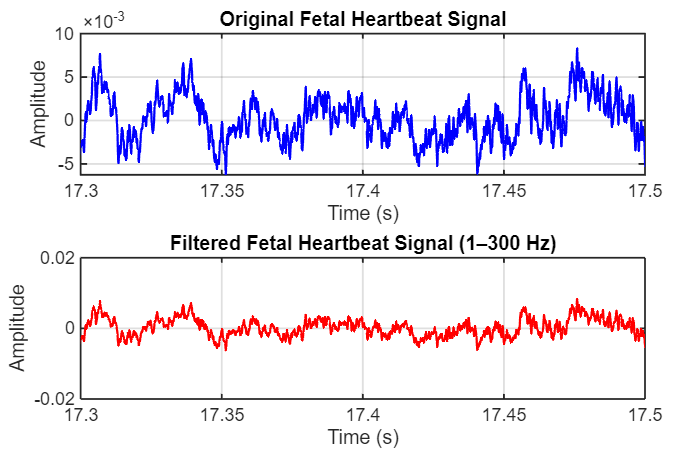



exportgraphics(gcf, 'FetalFilterPlot.pdf', 'ContentType', 'vector');

## Maternal Heartbeat Signal Bandpass Filter


% --- Bandpass Filter for Maternal Signal ---
maternalBpFilt = designfilt('bandpassiir', ...
    'FilterOrder', 6, ...
    'HalfPowerFrequency1', 1, ...
    'HalfPowerFrequency2', 600, ...
    'SampleRate', fsMaternal);

%maternalFiltered = filtfilt(maternalBpFilt, maternalSignal);
maternalFiltered = maternalSignal;


% --- Time vector ---
tMaternal = (0:length(maternalSignal)-1) / fsMaternal;

% --- Plotting ---
figure('Units','centimeters','Position',[5 5 18 12]); % Larger figure for better LaTeX export

tiledlayout(2,1,'Padding','compact','TileSpacing','compact'); % Better layout

% Font sizes
titleFont = 16;
labelFont = 14;
axisFont = 12;

% --- Original Maternal Signal ---
nexttile
plot(tMaternal, maternalSignal, 'b', 'LineWidth', 1.5);
title('Original Maternal Heartbeat Signal', 'FontSize', titleFont);
xlabel('Time (s)', 'FontSize', labelFont);
ylabel('Amplitude', 'FontSize', labelFont);
xlim([17.3, 17.5]);
ylim([-0.03, 0.03]);
grid on;
set(gca, 'FontSize', axisFont, 'LineWidth', 1.2);

% --- Filtered Maternal Signal ---
nexttile
plot(tMaternal, maternalFiltered, 'r', 'LineWidth', 1.5);
title('Filtered Maternal Heartbeat Signal (1–600 Hz)', 'FontSize', titleFont);
xlabel('Time (s)', 'FontSize', labelFont);
ylabel('Amplitude', 'FontSize', labelFont);
xlim([17.3, 17.5]);
ylim([-0.03, 0.03]);
grid on;
set(gca, 'FontSize', axisFont, 'LineWidth', 1.2);

disp('Bandpass filter applied to maternal signal (1–600 Hz).');

Bandpass filter applied to maternal signal (1–600 Hz).


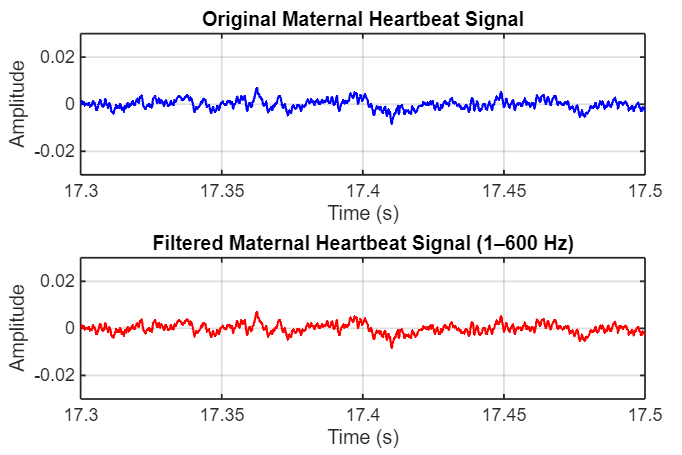

exportgraphics(gcf, 'MaternalFilterPlot.pdf', 'ContentType', 'vector');

## Active Noise Cancellation

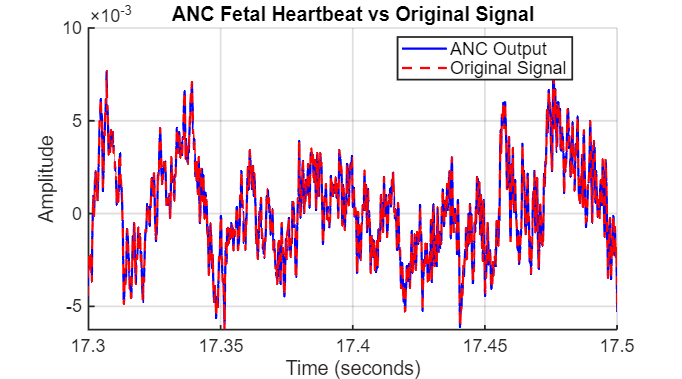

function [x_hat, error, weights] = ANC(signal, stepsize, filter_size, reference)
    samples = length(signal);
    weights = zeros(filter_size, 1);
    x_hat = zeros(1, samples);
    error = zeros(1, samples);

    for n = filter_size:samples
        % Construct predictor input u(n)
        u = reshape(reference(n:-1:n-filter_size+1), [], 1);  % Ensure column vector

        eta_hat = weights' * u;  % Should now be valid

        error(n) = signal(n) - eta_hat;

        weights = weights + stepsize * error(n) * u;

        x_hat(n) = error(n);
    end
end

[ANC_FHB,FHB_error,FHB_weights] = ANC(filteredSignal,0.01,128,maternalFiltered);
t_anc = (0:length(ANC_FHB)-1) / fsFetal;
t = (0:length(filteredSignal)-1) / fsFetal;

figure('Units','centimeters','Position',[5 5 18 10]);  % Proper size for LaTeX export
hold on;

% Plot ANC Output (blue solid)
plot(t_anc, ANC_FHB, 'b', 'LineWidth', 1.5);           

% Plot Original Filtered Signal (red dashed)
plot(t, filteredSignal, 'r--', 'LineWidth', 1.5);       

xlabel('Time (seconds)', 'FontSize', 14);
ylabel('Amplitude', 'FontSize', 14);
title('ANC Fetal Heartbeat vs Original Signal', 'FontSize', 16);

% Set common x-axis limits
xlim([17.3, 17.5]);

grid on;

% Set legend with increased font size
legend('ANC Output', 'Original Signal', 'Location', 'best', 'FontSize', 12);

% Increase tick label font sizes and axis line width
set(gca, 'FontSize', 12, 'LineWidth', 1.2);

exportgraphics(gcf, 'ANC_vs_Original.pdf', 'ContentType', 'vector');

## PCA 

% Parameters
windowSize = 1024;
overlap = 512;

% Use ANC output (denoised signal)
frames = buffer(ANC_FHB, windowSize, overlap, 'nodelay');

% Normalize columns (zero mean per frame)
frames = frames - mean(frames, 1);

% PCA decomposition
[coeff, score, latent, tsquared, explained] = pca(frames');

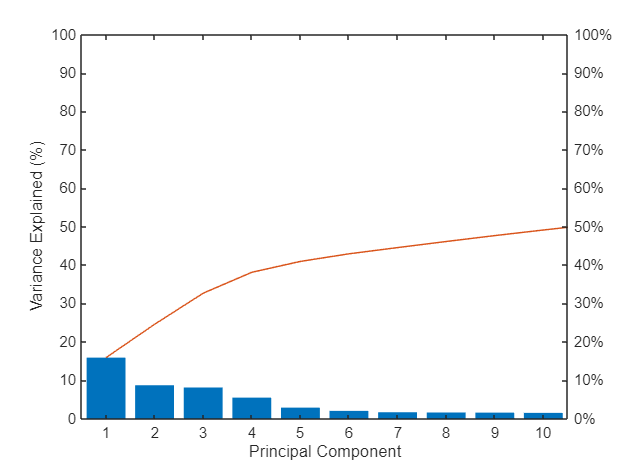


% Variance plot
figure;
pareto(explained);
xlabel('Principal Component');
ylabel('Variance Explained (%)');

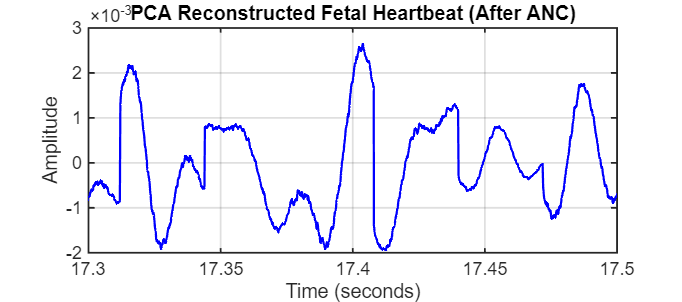


% Reconstruct using only first principal component
k = 2; % number of PCs to keep
fs = fsFetal;  % from your ANC input

reconstructed = score(:, 1:k) * coeff(:, 1:k)';  % low-dimensional reconstruction
reconstructed = reconstructed';  % reshape to original framing

% Flatten and construct time vector
reconstructedSignal = reconstructed(:);
t = (0:length(reconstructedSignal)-1) / fs;

% Plot the reconstructed waveform
% Plot the reconstructed waveform (publication quality)
figure('Units','centimeters','Position',[5 5 18 8]);  % Wider for single plot

plot(t, reconstructedSignal, 'b', 'LineWidth', 1.5);
xlabel('Time (seconds)', 'FontSize', 14);
ylabel('Amplitude', 'FontSize', 14);
title('PCA Reconstructed Fetal Heartbeat (After ANC)', 'FontSize', 16);

xlim([17.3, 17.5]);
grid on;

set(gca, 'FontSize', 12, 'LineWidth', 1.2);

exportgraphics(gcf, 'PCA_Reconstructed_FHB.pdf', 'ContentType', 'vector');


% Normalize and save as WAV file
reconstructedSignalNorm = reconstructedSignal / max(abs(reconstructedSignal));
outputFilename = 'PCA_Reconstructed_FHB.wav';
audiowrite(outputFilename, reconstructedSignalNorm, fs);
disp(['WAV file saved as: ', outputFilename]);

WAV file saved as: PCA_Reconstructed_FHB.wav


## Comparison 

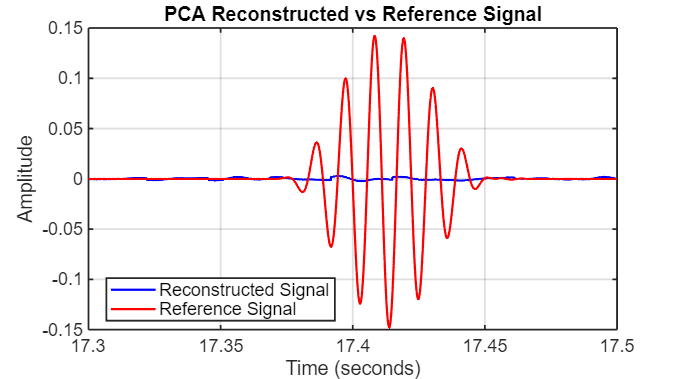

[filename2, pathname2] = uigetfile({'*.wav', 'WAV Files (*.wav)'}, 'Select the Reference Signal');
if isequal(filename2, 0)
    disp('User canceled reference signal selection.');
    return;
end

filePath2 = fullfile(pathname2, filename2);
[refSignal, fsRef] = audioread(filePath2);

if size(refSignal, 2) == 2
    refSignal = mean(refSignal, 2);  % Convert to mono if stereo
end


% First, match lengths of signals and time vector
minLen = min(length(reconstructedSignal), length(refSignal));
t_plot = (0:minLen-1) / fsRef;  % assuming you're using fsRef for both signals

% Trim signals to same length
reconstructedSignal_trimmed = reconstructedSignal(1:minLen);
refSignal_trimmed = refSignal(1:minLen);

% Plot both signals
figure('Units','centimeters','Position',[5 5 18 10]);  % Optimal size for Overleaf

% Plot Reconstructed Signal (blue)
plot(t_plot, reconstructedSignal_trimmed, 'b', 'LineWidth', 1.5, 'DisplayName', 'Reconstructed Signal');
hold on;

% Plot Reference Signal (red)
plot(t_plot, refSignal_trimmed, 'r', 'LineWidth', 1.5, 'DisplayName', 'Reference Signal');

xlabel('Time (seconds)', 'FontSize', 14);
ylabel('Amplitude', 'FontSize', 14);
title('PCA Reconstructed vs Reference Signal', 'FontSize', 16);

xlim([17.3, 17.5]);
grid on;

legend('show', 'FontSize', 12, 'Location', 'best');
set(gca, 'FontSize', 12, 'LineWidth', 1.2);
exportgraphics(gcf, 'PCA_vs_Reference.pdf', 'ContentType', 'vector');